Basic second order system response

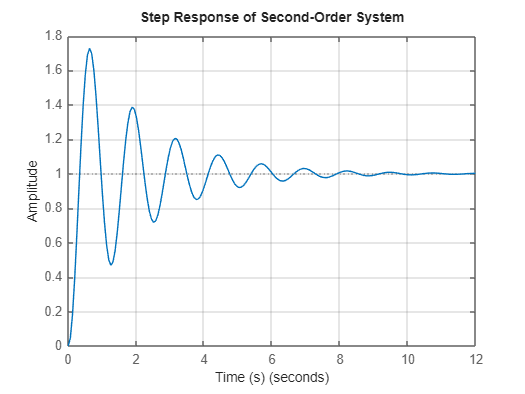

% Define parameters
wn = 5;           % Natural frequency (rad/s)
zeta = 0.1;       % Damping ratio

% Create the transfer function
gain = wn^2;                             % Numerator = wn^2
char_eqn = [1 2*zeta*wn wn^2];               % Denominator = s^2 + 2*zeta*wn*s + wn^2
sys = tf(gain, char_eqn);                     % Create transfer function model

% Plot the step response
figure;
step(sys);
title('Step Response of Second-Order System');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

Visualizing change in damping ratio

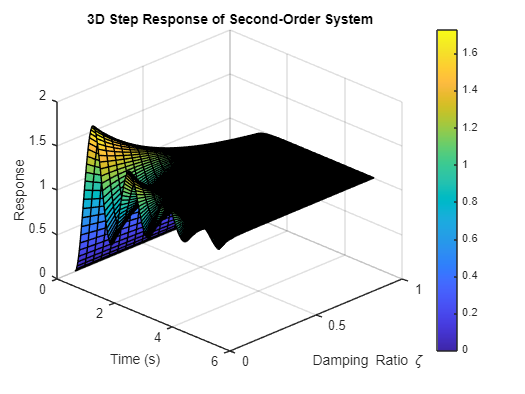

% Parameters
wn = 5;                              % Natural frequency (rad/s)
zeta_values = linspace(0.1, 1, 20);  % Damping ratio from 0.1 to 1
t = linspace(0, 5, 200);             % Time vector from 0 to 5 seconds

% Initialize matrix to hold step responses
Y = zeros(length(t), length(zeta_values));

% Loop through each damping ratio and compute step response
for i = 1:length(zeta_values)
    zeta = zeta_values(i);
    gain = wn^2;
    char_eqn = [1 2*zeta*wn wn^2];
    sys = tf(gain, char_eqn);
    y = step(sys, t);       % Compute step response at times t
    Y(:, i) = y;            % Store in response matrix
end

% Create meshgrid for surface plot
[ZETA, T] = meshgrid(zeta_values, t);  % ZETA = zeta axis, T = time

% Plot the surface
figure;
surf(T, ZETA, Y);
xlabel('Time (s)');
ylabel('Damping Ratio \zeta');
zlabel('Response');
title('3D Step Response of Second-Order System');
colorbar;
view(45, 30);  % Adjust viewing angle